[popAudio,FS] = audioread("200805_001.WAV")

popAudio =     0.0006    0.0006
    0.0013    0.0013
    0.0019    0.0019
    0.0025    0.0025
    0.0031    0.0032
    0.0038    0.0038
    0.0044    0.0044
    0.0050    0.0050
    0.0056    0.0057
    0.0063    0.0063


FS = 192000

popAudioL = popAudio(:,1);
popAudioR = popAudio(:,2);

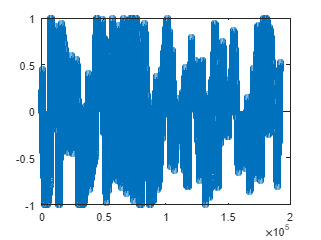

figure(1); clf; title('Leafy Splurge Audio');
stem(popAudioL(1:FS))

figure(2); clf;
filteredWind = highpass(popAudioL,.011);

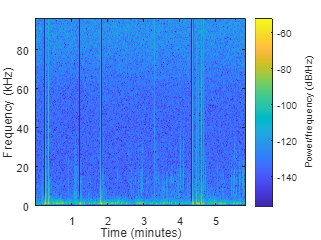

spectrogram(filteredWind(1:end/2),hann(512),128,512,FS,'yaxis');

% Check pop at 2:16 with headphones

sound(filteredWind())